## **PART A**

**Load input data and Scatter Plot of Training Data   **

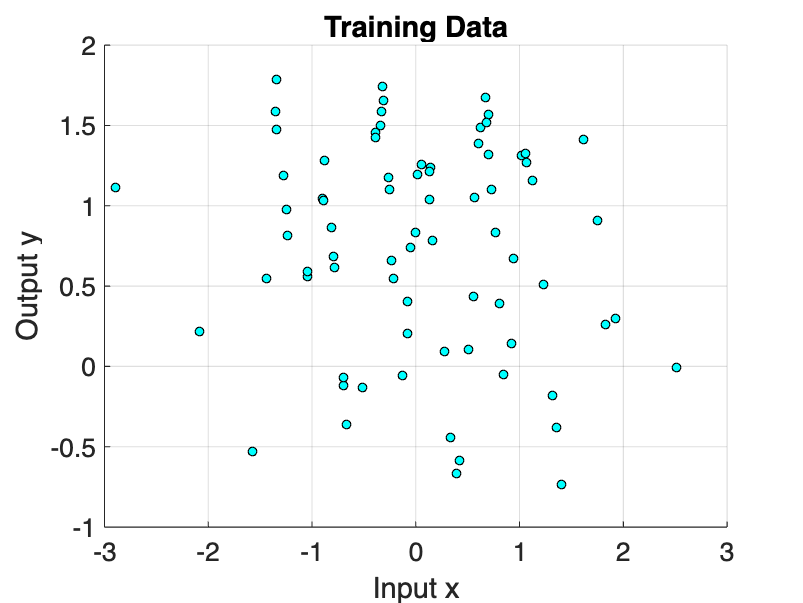

% Load data from 'cw1a.mat'
load('cw1a.mat');  % Assumes 'cw1a.mat' contains variables 'x' and 'y'

% Generate scatter plot
figure;
scatter(x, y, 15, 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'c');
% Axis labels and titles
xlabel('Input x', 'FontSize', 12);
ylabel('Output y', 'FontSize', 12);
title('Training Data', 'FontSize', 14, 'FontWeight', 'bold');
grid on;
set(gca, 'FontSize', 12);

**Fitting Gaussian Process Function  **

meanfunc = @meanZero;           
covfunc = @covSEiso;             % Squared exponential isotropic covariance
likfunc = @likGauss;             % Gaussian likelihood

hyp.mean = [];                    
hyp.cov = [-1; 0];                % Initial log hyperparameters for covSEiso
hyp.lik = 0;                      % Initial log noise standard deviation

% Inference method for exact Gaussian likelihood
inf = @infGaussLik;

% Optimising hyperparameters 
hyp2 = minimize(hyp, @gp, -100, inf, meanfunc, covfunc, likfunc, x, y);

Function evaluation      0;  Value 9.291004e+01
Function evaluation      5;  Value 8.087778e+01
Function evaluation      7;  Value 8.021862e+01
Function evaluation      9;  Value 8.002546e+01
Function evaluation     15;  Value 6.375024e+01
Function evaluation     18;  Value 6.367546e+01
Function evaluation     27;  Value 1.199029e+01
Function evaluation     31;  Value 1.194074e+01
Function evaluation     33;  Value 1.190108e+01
Function evaluation     36;  Value 1.189901e+01
Function evaluation     39;  Value 1.189900e+01
Function evaluation     41;  Value 1.189900e+01
Function evaluation     43;  Value 1.189900e+01
Function evaluation     46;  Value 1.189900e+01
Function evaluation     48;  Value 1.189900e+01
Function evaluation     55;  Value 1.189900e+01
Function evaluation     56;  Value 1.189900e+01


hyp2.cov

ans =    -2.0540
   -0.1087


hyp2.lik

ans = -2.1385


% Test inputs (xs)
xs = linspace(min(x), max(x), 500)';  

% Predictions using optimised hyperparameters
[mu, s2] = gp(hyp2, inf, meanfunc, covfunc, likfunc, x, y, xs);
[nlml, dnlmlz] = gp(hyp2, inf, meanfunc, covfunc, likfunc, x, y);
nlml

nlml = 11.8990

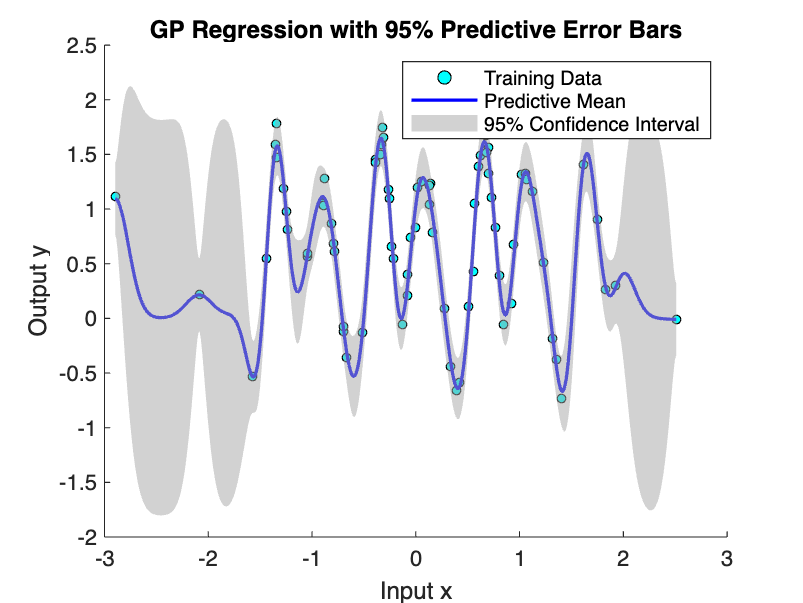


% 95% confidence intervals
upper = mu + 2*sqrt(s2);
lower = mu - 2*sqrt(s2);

figure;
hold on;
% Plot training data
scatter(x, y, 15, 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'c');
% Plot predictive mean
plot(xs, mu, 'b-', 'LineWidth', 1.5);
% Fill the confidence interval
fill([xs; flipud(xs)], [upper; flipud(lower)], [0.65 0.65 0.65], 'EdgeColor', 'none', 'FaceAlpha', 0.5);
hold off;
xlabel('Input x');
ylabel('Output y');
title('GP Regression with 95% Predictive Error Bars');
legend('Training Data', 'Predictive Mean', '95% Confidence Interval');

**Heat Maps (helps understand behaviour of kernel/ covariance function)**

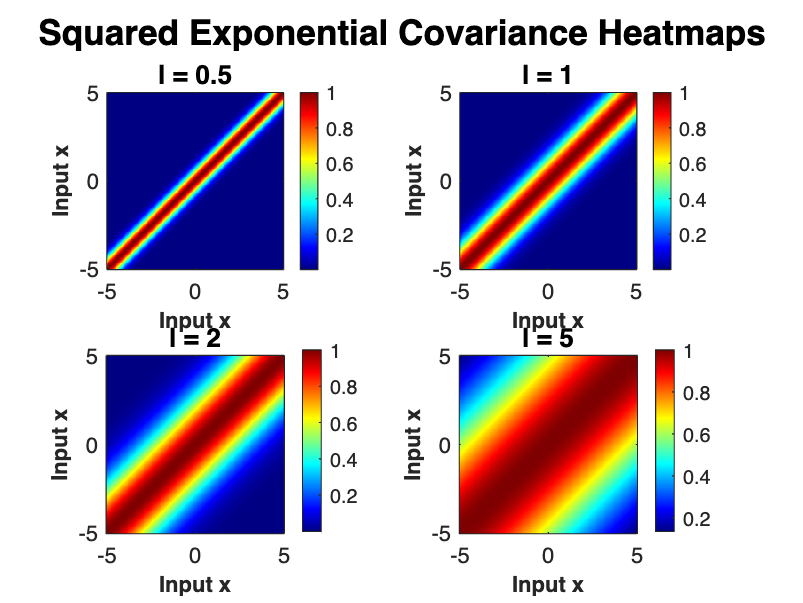

% Input points
input = linspace(-5, 5, 200)'; 

% Define a set of length-scale parameters to visualise
length_scales = [0.5, 1, 2, 5];  
sigma_f = 1;  % signal standard deviation

% Plotting covariance heatmaps
figure;
for i = 1:length(length_scales)
    ell = length_scales(i);
    
    % Covariance function parameters
    covfunc = @covSEiso;
    hyp.cov = [log(ell); log(sigma_f)]; 
    
    % Covariance matrix with jitter
    K = feval(covfunc, hyp.cov, input) + (1e-6 * eye(length(input))); 
    
    % Plot covariance matrix as a heatmap
    subplot(2, 2, i);  % Arrange plots in a 2x2 grid
    imagesc(input, input, K);  % Display the covariance matrix as an image
    axis xy;  % Correct the y-axis orientation
    axis square;
    colormap(jet);
    colorbar;  % color scale
    xlabel('Input x', 'FontSize', 10, 'FontWeight', 'bold');  
    ylabel('Input x', 'FontSize', 10, 'FontWeight', 'bold');  
    title(['l = ' num2str(ell)], 'FontSize', 12, 'FontWeight', 'bold');
end

% Overall title for the figure
sgtitle('Squared Exponential Covariance Heatmaps', 'FontSize', 16, 'FontWeight', 'bold');

## **PART B**

**Finding hyperparameter optima via random restarts**

meanfunc = @meanZero;            
covfunc = @covSEiso;             % Squared Exponential Isotropic covariance
likfunc = @likGauss;             % Gaussian likelihood
inf = @infGaussLik;

% Number of random restarts
num_restarts = 10;

% Preallocate storage for optimised hyperparameters and NLMLs
hyp_opts = cell(num_restarts,1);
nlmls = zeros(num_restarts,1);            
log_hyperparams = zeros(num_restarts,3);  % [log_ell, log_sigma_f, log_sigma_n]

% Perform Multiple Random restarts
for i = 1:num_restarts
    % Randomly initialise hyperparameters within specified ranges
    initial_length_scale = log(0.1 + (2 - 0.1) * rand());    % log(ell) between log(0.1) and log(2)
    initial_signal_std = log(0.5 + (2 - 0.5) * rand());      % log(sigma_f) between log(0.5) and log(2)
    initial_noise_std = log(0.05 + (1 - 0.05) * rand());     % log(sigma_n) between log(0.05) and log(1)
    
    % Set initial hyperparameters
    initial_hyp.mean = [];                              
    initial_hyp.cov = [initial_length_scale; initial_signal_std]; % [log(ell); log(sigma_f)]
    initial_hyp.lik = initial_noise_std; % log(sigma_n)
    
    % Optimise hyperparameters
    hyp_opts{i} = minimize(initial_hyp, @gp, -100, inf, meanfunc, covfunc, likfunc, x, y);
    
    % Compute NLML for the optimised hyperparameters
    [nlmls(i), ~] = gp(hyp_opts{i}, inf, meanfunc, covfunc, likfunc, x, y);
    
    % Store the log hyperparameters
    log_hyperparams(i,1) = hyp_opts{i}.cov(1);   % log(ell)
    log_hyperparams(i,2) = hyp_opts{i}.cov(2);   % log(sigma_f)
    log_hyperparams(i,3) = hyp_opts{i}.lik;      % log(sigma_n)
end

Function evaluation      0;  Value 6.448629e+01
Function evaluation      7;  Value 4.886672e+01
Function evaluation     11;  Value 1.540884e+01
Function evaluation     14;  Value 1.385019e+01
Function evaluation     16;  Value 1.206764e+01
Function evaluation     19;  Value 1.193998e+01
Function evaluation     21;  Value 1.189913e+01
Function evaluation     24;  Value 1.189905e+01
Function evaluation     26;  Value 1.189901e+01
Function evaluation     28;  Value 1.189901e+01
Function evaluation     30;  Value 1.189900e+01
Function evaluation     32;  Value 1.189900e+01
Function evaluation     34;  Value 1.189900e+01
Function evaluation     36;  Value 1.189900e+01
Function evaluation     38;  Value 1.189900e+01
Function evaluation     40;  Value 1.189900e+01
Function evaluation     43;  Value 1.189900e+01
Function evaluation     45;  Value 1.189900e+01
Function evaluation     49;  Value 1.189900e+01
Function evaluation      0;  Value 4.627089e+02
Function evaluation      9;  Value 1.217


% Create a table to display the results
Restart = (1:num_restarts)';
Log_Ell = log_hyperparams(:,1);
Log_Sigma_f = log_hyperparams(:,2);
Log_Sigma_n = log_hyperparams(:,3);
NLML = nlmls;

% Convert log hyperparameters to natural domain
Ell = exp(Log_Ell);
Sigma_f = exp(Log_Sigma_f);
Sigma_n = exp(Log_Sigma_n);

% Combine Data into a Table 
Results_Table = table(Restart, Log_Ell, Log_Sigma_f, Log_Sigma_n, Ell, Sigma_f, Sigma_n, NLML, ...
    'VariableNames', {'Restart', 'Log_Ell', 'Log_Sigma_f', 'Log_Sigma_n', 'Ell', 'Sigma_f', 'Sigma_n', 'NLML'});

% Display the table
disp(Results_Table);

    Restart    Log_Ell    Log_Sigma_f    Log_Sigma_n      Ell      Sigma_f    Sigma_n     NLML 
    _______    _______    ___________    ___________    _______    _______    _______    ______

       1       -2.054      -0.10871        -2.1385      0.12823    0.89699    0.11783    11.899
       2       2.0715      -0.36412       -0.41088       7.9367    0.69481    0.66306     78.22
       3       -2.054      -0.10871        -2.1385      0.12823    0.89699    0.11783    11.899
       4       -2.054      -0.10871        -2.1385      0.12823    0.89699    0.11783    11.899
       5       2.0847      -0.36248       -0.41087       8.0421    0.69595    0.66307     78.22
       6       -2.054      -0.10871        -2.1385     


% Best hyperparameters (lowest NLML)
[best_nlml, best_idx] = min(NLML);
best_hyp = hyp_opts{best_idx};

fprintf('\nBest NLML: %.4f from Restart #%d\n', best_nlml, best_idx);


Best NLML: 11.8990 from Restart #10


fprintf('Optimized Hyperparameters (Natural Domain):\n');

Optimized Hyperparameters (Natural Domain):


fprintf('  Length-scale (ell): %.5f\n', exp(best_hyp.cov(1)));

  Length-scale (ell): 0.12823


fprintf('  Signal Std Dev (sigma_f): %.5f\n', exp(best_hyp.cov(2)));

  Signal Std Dev (sigma_f): 0.89699


fprintf('  Noise Std Dev (sigma_n): %.5f\n', exp(best_hyp.lik));

  Noise Std Dev (sigma_n): 0.11783


## **PART C**

meanfunc = @meanZero;            
covfunc = @covPeriodic;       % Periodic covariance function
likfunc = @likGauss;          % Gaussian likelihood

hyp.mean = [];               
hyp.cov = [-1; 0; log(1)];
hyp.lik = 0;                 
inf = @infGaussLik;

% Optimise hyperparameters
hyp2 = minimize(hyp, @gp, -100, inf, meanfunc, covfunc, likfunc, x, y);

Function evaluation      0;  Value 8.323827e+01
Function evaluation      7;  Value 5.704895e+01
Function evaluation     10;  Value 4.200345e+00
Function evaluation     15;  Value -1.194478e+00
Function evaluation     20;  Value -2.796747e+01
Function evaluation     23;  Value -2.842821e+01
Function evaluation     26;  Value -2.843297e+01
Function evaluation     28;  Value -2.844099e+01
Function evaluation     30;  Value -2.845275e+01
Function evaluation     32;  Value -2.846178e+01
Function evaluation     34;  Value -2.847784e+01
Function evaluation     36;  Value -2.848725e+01
Function evaluation     38;  Value -2.850407e+01
Function evaluation     40;  Value -2.851425e+01
Function evaluation     42;  Value -2.853255e+01
Function evaluation     44;  Value -2.854392e+01
Function evaluation     46;  Value -2.856455e+01
Function evaluation     48;  Value -2.857771e+01
Function evaluation     50;  Value -2.860185e+01
Function evaluation     52;  Value -2.861828e+01
Function evaluation    

hyp2.cov

ans =    -0.3499
   -0.0009
   -0.3651


hyp2.lik

ans = -2.4642

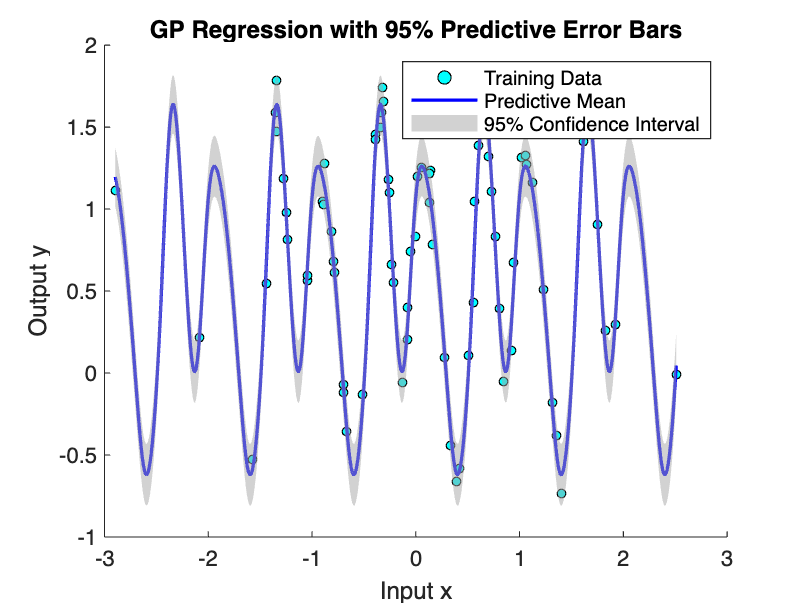


% Test inputs (xs)
xs = linspace(min(x), max(x), 500)';  
% Perform prediction using the optimised hyperparameters
[mu, s2] = gp(hyp2, inf, meanfunc, covfunc, likfunc, x, y, xs);

% Calculate 95% confidence intervals
upper = mu + 2*sqrt(s2);
lower = mu - 2*sqrt(s2);

% Plot the results
figure;
hold on;
% Plot training data
scatter(x, y, 15, 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'c');
% Plot predictive mean
plot(xs, mu, 'b-', 'LineWidth', 1.5);
% Fill the confidence interval
fill([xs; flipud(xs)], [upper; flipud(lower)], [0.65 0.65 0.65], 'EdgeColor', 'none', 'FaceAlpha', 0.5);
hold off;
xlabel('Input x');
ylabel('Output y');
title('GP Regression with 95% Predictive Error Bars');
legend('Training Data', 'Predictive Mean', '95% Confidence Interval');

## PART D 

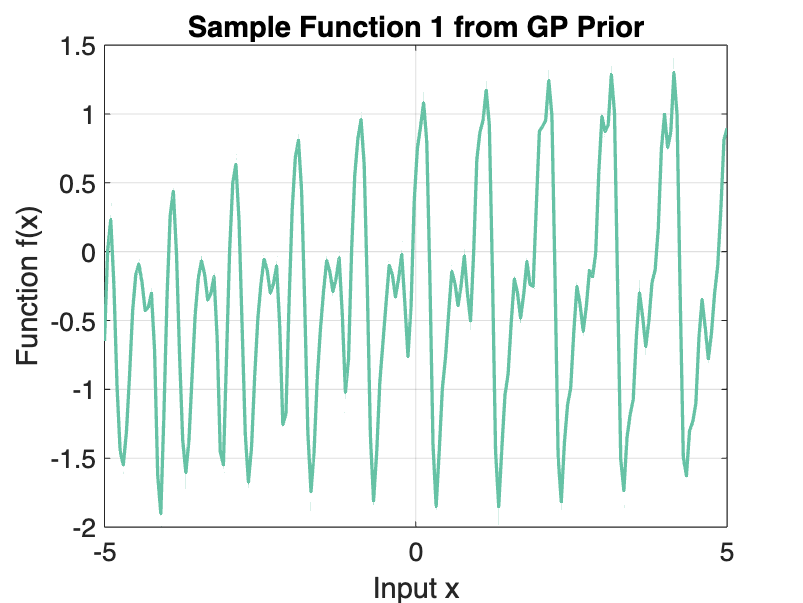

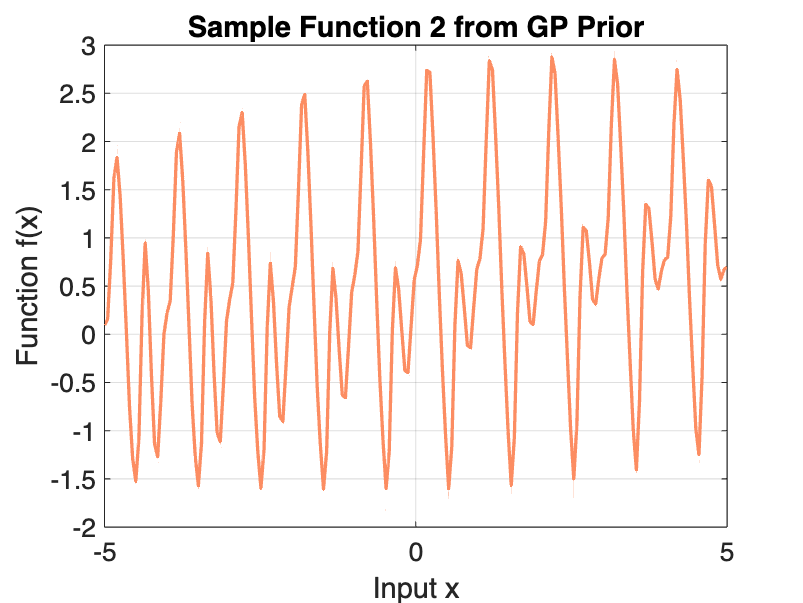

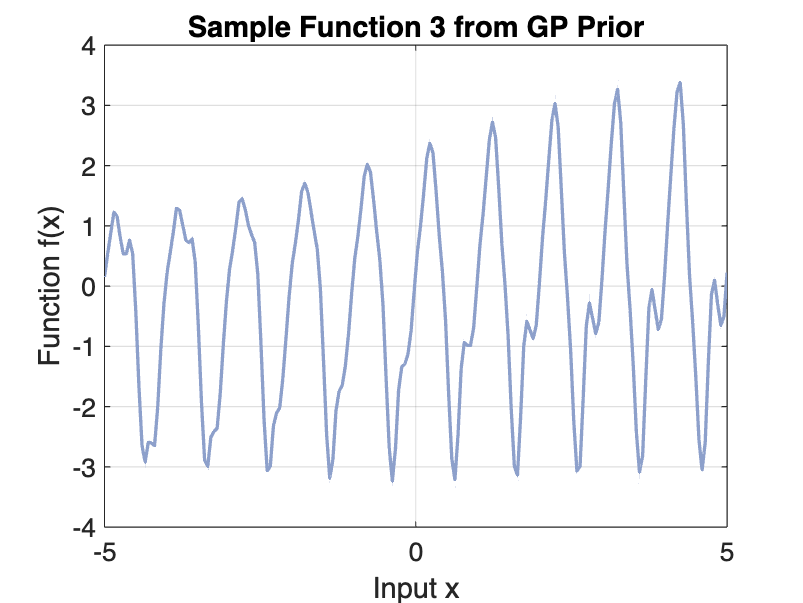

% Define input points
input_1 = linspace(-5, 5, 200)';  
n = size(input_1,1);

meanfunc = @meanZero;            
covfunc = {@covProd, {@covPeriodic, @covSEiso}};
likfunc = @likGauss; % Gaussian likelihood
hyp.mean = [];                  
hyp.cov = [-0.5; 0; 0; 2; 0]; 
hyp.lik = [];              

% Covariance matrix with jitter
K = feval(covfunc{:}, hyp.cov, input_1) + (1e-5 * eye(length(input_1)));
% Cholesky decomposition (lower-triangular)
L = chol(K, 'lower');


% Generate sample functions and store them
rng(1);
num_samples = 3; % Number of functions to sample

colors = {
    [102/255, 194/255, 165/255],   % Soft Green
    [252/255, 141/255, 98/255],    % Soft Orange
    [141/255, 160/255, 203/255]    % Soft Purple
};

f_samples = cell(num_samples, 1);

% Generate and plot each sample function separately
for i = 1:num_samples
    f = L * randn(n,1); 
    f_samples{i} = f;
    
    % Plot the sample function
    figure;
    plot(input_1, f, 'LineWidth', 1.5, 'Color', colors{i});    
    % Customise the plot
    xlabel('Input x', 'FontSize', 12);
    ylabel('Function f(x)', 'FontSize', 12);
    title(sprintf('Sample Function %d from GP Prior', i), 'FontSize', 14, 'FontWeight', 'bold');
    grid on;
    set(gca, 'FontSize', 12);
end

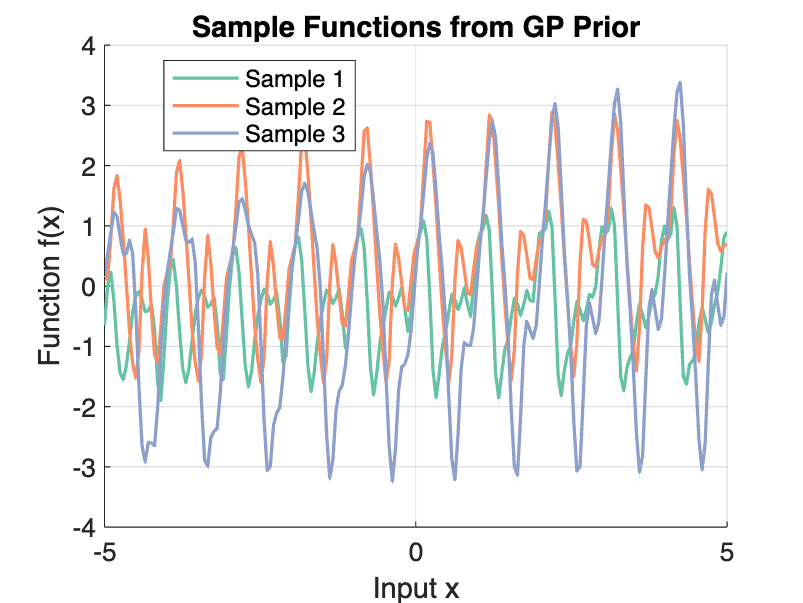


% Plot all sample functions together
figure;
hold on;

for i = 1:num_samples
    plot(input_1, f_samples{i}, 'LineWidth', 1.5, 'Color', colors{i}, 'DisplayName', sprintf('Sample %d', i));
end

% Customize the plot
xlabel('Input x', 'FontSize', 12);
ylabel('Function f(x)', 'FontSize', 12);
title('Sample Functions from GP Prior', 'FontSize', 14, 'FontWeight', 'bold');  % Main title in bold
legend('Location', 'best');
grid on;
set(gca, 'FontSize', 12);
hold off;

## PART E 

clear all; close all; clc;

% Load 'cw1e.mat'
load('cw1e.mat'); 

disp('Size of x:'); disp(size(x));  

Size of x:
   121     2



disp('Size of y:'); disp(size(y));  

Size of y:
   121     1



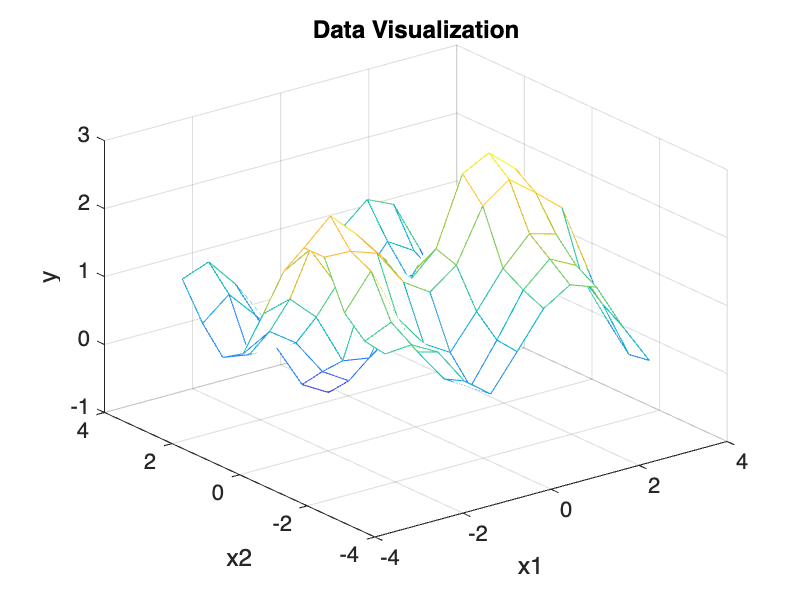


% Reshape data for plotting 
X1 = reshape(x(:,1), 11, 11);
X2 = reshape(x(:,2), 11, 11);
Y = reshape(y, 11, 11);

figure;
mesh(X1, X2, Y);
xlabel('x1');
ylabel('x2');
zlabel('y');
title('Data Visualization');
grid on;
rotate3d on;


%% GP Model with Sum of Two covSEard
meanfunc = @meanZero;  
hyp2.mean = [];   
covfunc2 = {@covSum, {@covSEard, @covSEard}};
likfunc = @likGauss;   

% Initialise hyperparameters
hyp2.cov = 0.1 * randn(6, 1);  % random values to break symmetry
hyp2.lik = log(0.1); 

% Number of iterations for optimisation
num_iters = 100;
% Optimising hyperparameters
hyp2_opt = minimize(hyp2, @gp, -num_iters, @infGaussLik, meanfunc, covfunc2, likfunc, x, y);

Function evaluation      0;  Value 2.467486e+01
Function evaluation      6;  Value -1.746566e+01
Function evaluation      9;  Value -1.911310e+01
Function evaluation     11;  Value -1.930458e+01
Function evaluation     14;  Value -2.003941e+01
Function evaluation     16;  Value -2.039930e+01
Function evaluation     21;  Value -2.718142e+01
Function evaluation     24;  Value -4.951555e+01
Function evaluation     26;  Value -5.839015e+01
Function evaluation     29;  Value -6.146117e+01
Function evaluation     31;  Value -6.268803e+01
Function evaluation     33;  Value -6.367514e+01
Function evaluation     35;  Value -6.414851e+01
Function evaluation     37;  Value -6.424166e+01
Function evaluation     39;  Value -6.442130e+01
Function evaluation     41;  Value -6.480754e+01
Function evaluation     43;  Value -6.562740e+01
Function evaluation     47;  Value -6.591136e+01
Function evaluation     49;  Value -6.599019e+01
Function evaluation     51;  Value -6.604125e+01
Function evaluation  


% Compute the NLML with optimised hyperparameters
[nlZ2, ~] = gp(hyp2_opt, @infGaussLik, meanfunc, covfunc2, likfunc, x, y);

% Make predictions at training inputs 
[mu2_train, s2_2_train] = gp(hyp2_opt, @infGaussLik, meanfunc, covfunc2, likfunc, x, y, x);

% Compute MSE on training data
mse2_train = mean((mu2_train - y).^2);

% Display the optimised hyperparameters
disp('Optimised hyperparameters (Model 2):');

Optimised hyperparameters (Model 2):



disp('First covSEard:');

First covSEard:


disp('Length scales (ell):'); disp(exp(hyp2_opt.cov(1:2)));

Length scales (ell):
    1.4468
  755.5420



disp('Signal variance (sf):'); disp(exp(hyp2_opt.cov(3)));

Signal variance (sf):
    1.0929




disp('Second covSEard:');

Second covSEard:


disp('Length scales (ell):'); disp(exp(hyp2_opt.cov(4:5)));

Length scales (ell):
  547.7429
    0.9849



disp('Signal variance (sf):'); disp(exp(hyp2_opt.cov(6)));

Signal variance (sf):
    0.7125



disp('Noise standard deviation (sn):'); disp(exp(hyp2_opt.lik));

Noise standard deviation (sn):
    0.0977




% NLML and MSE
fprintf('Model 2 NLML: %.4f\n', nlZ2);

Model 2 NLML: -66.3633


fprintf('Model 2 Training MSE: %.4f\n', mse2_train);

Model 2 Training MSE: 0.0083


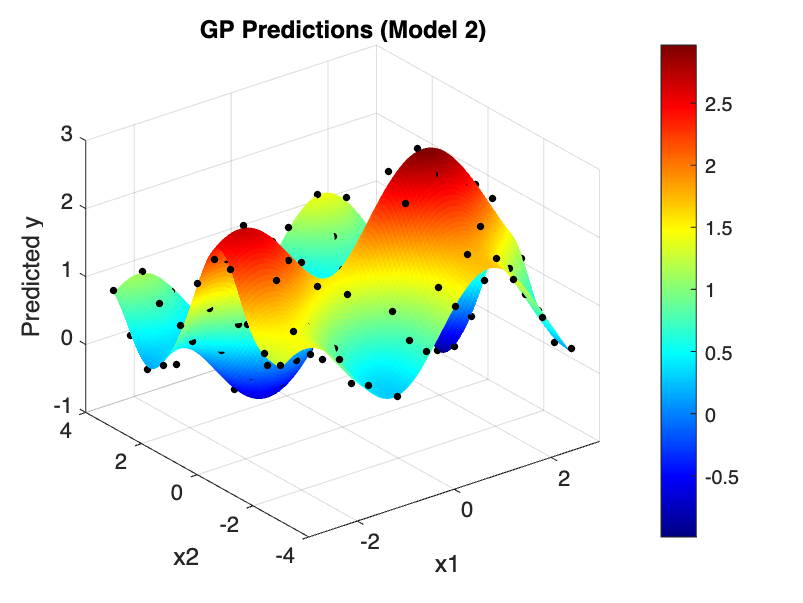


% Range for each input dimension
x1_min = min(x(:,1));
x1_max = max(x(:,1));
x2_min = min(x(:,2));
x2_max = max(x(:,2));

% Number of points along each dimension for the finer grid
n_fine = 100;  

% Generate evenly spaced points within the range
x1_fine = linspace(x1_min, x1_max, n_fine);
x2_fine = linspace(x2_min, x2_max, n_fine);

[X1_fine, X2_fine] = meshgrid(x1_fine, x2_fine);
x_test = [X1_fine(:), X2_fine(:)];

% Predictions with Model 2 on the finer grid
[mu2_fine, s2_2_fine] = gp(hyp2_opt, @infGaussLik, meanfunc, covfunc2, likfunc, x, y, x_test);
MU2_fine = reshape(mu2_fine, n_fine, n_fine);
S2_2_fine = reshape(s2_2_fine, n_fine, n_fine);

% Plot predictive mean as a surface
figure;
surf(X1_fine, X2_fine, MU2_fine, 'EdgeColor', 'none');
xlabel('x1');
ylabel('x2');
zlabel('Predicted y');
title('GP Predictions (Model 2)');
grid on;
rotate3d on;
colormap jet;
colorbar;
hold on;
plot3(x(:,1), x(:,2), y, 'k.', 'MarkerSize', 10);
hold off;

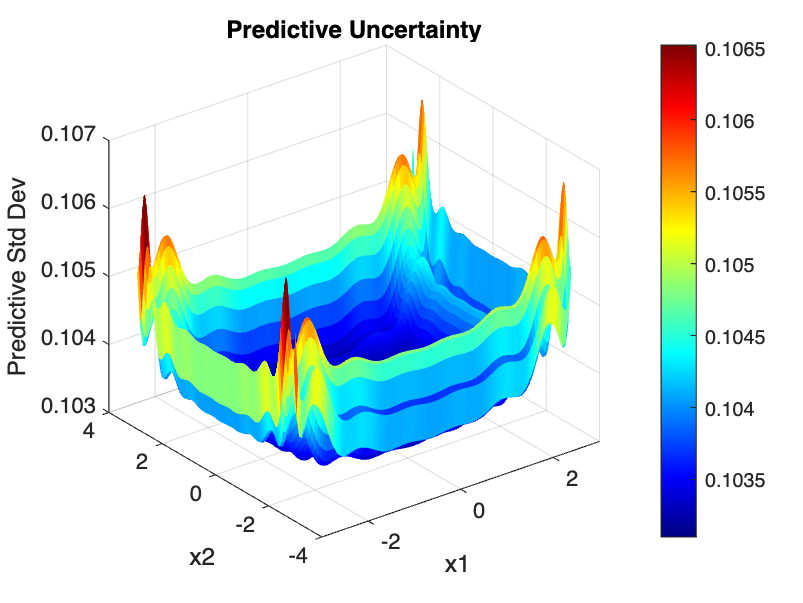


%% Predictive Uncertainty
% Compute the predictive standard deviation
STD2_fine = sqrt(S2_2_fine);
% Predictive standard deviation as a surface
figure;
surf(X1_fine, X2_fine, STD2_fine, 'EdgeColor', 'none');
xlabel('x1');
ylabel('x2');
zlabel('Predictive Std Dev');
title('Predictive Uncertainty');
grid on;
rotate3d on;
colormap jet;
colorbar;

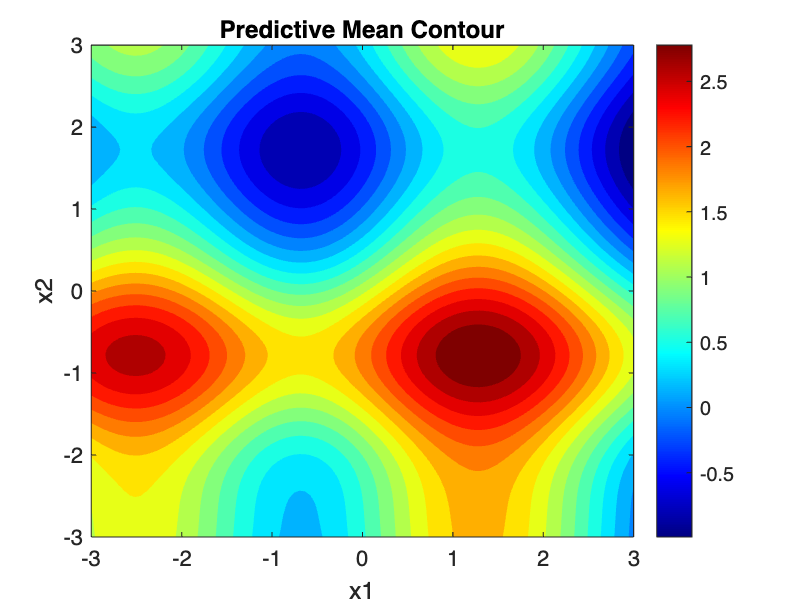


% Contour plot of predictive mean
figure;
contourf(X1_fine, X2_fine, MU2_fine, 20, 'LineColor', 'none');
xlabel('x1');
ylabel('x2');
title('Predictive Mean Contour');
colormap jet;
colorbar;

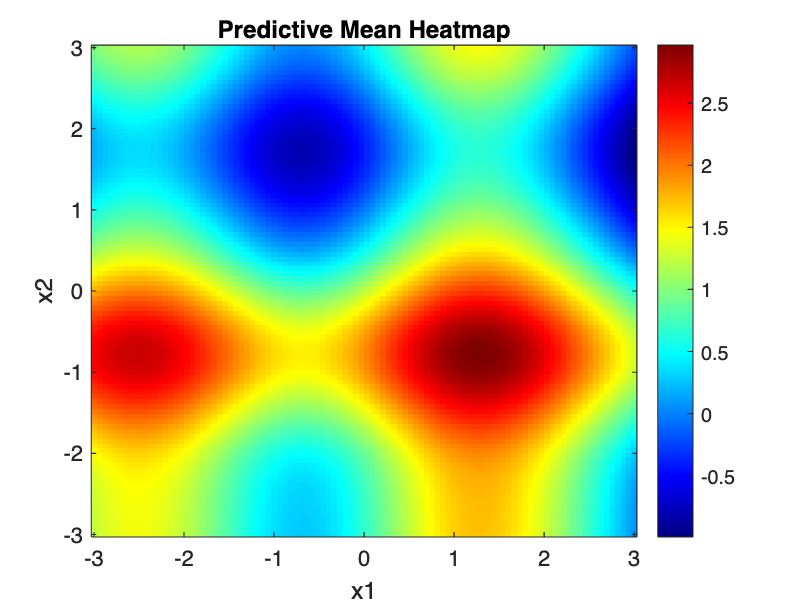


% Heatmap of the predictive mean
figure;
imagesc(x1_fine, x2_fine, MU2_fine);
axis xy;  % Correct the axis direction
xlabel('x1');
ylabel('x2');
title('Predictive Mean Heatmap');
colormap jet;
colorbar;